QAM Symbol with Noise

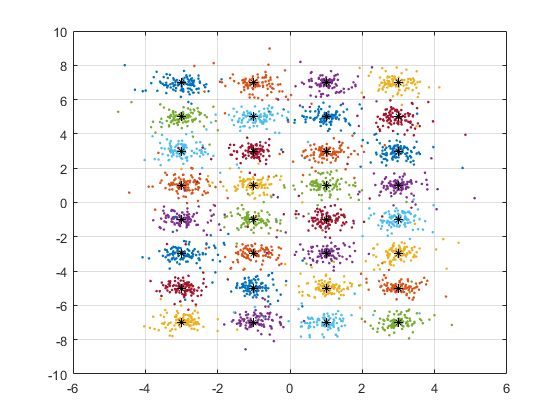

%qam4 = [-1-1i 1-1i 1+1i -1+1i];
%qam4 = qam4/mean(abs(qam4));
%plot(qam4,'*');
%qam16 = [-3-3i -3-1i -3+3i -3+1i -1-3i -1-1i -1+3i -1+1i 3-3i 3-1i 3+3i 3+1i 1-3i 1-1i 1+3i 1+1i];
%qam16 = qam16/mean(abs(qam16));
%plot(qam16,'.');
qam32 = [-3+7i -1+7i 3+7i 1+7i -3+5i -1+5i 3+5i 1+5i -3+1i -1+1i 3+1i 1+1i -3+3i -1+3i 3+3i 1+3i -3-7i -1-7i 3-7i 1-7i -3-5i -1-5i 3-5i 1-5i -3-1i -1-1i 3-1i 1-1i -3-3i -1-3i 3-3i 1-3i];
%qam32 = qam32/mean(abs(qam32));

Spr=(mean(abs(qam32)))^2;
snrdB=15;
SNR=10^(snrdB/10);
sigmaN=Spr/SNR;
t=100;
l=length(qam32);
Xdemcap=zeros([t l]);
for i=1:t
    H = sqrt(2)*randn(l,l) + 1i*sqrt(2)*randn(l,l);
    Y=H*qam32.' + sqrt(sigmaN)*randn([l,1]);
    %Xcap=pinv(H)*Y;                                %MSME
    Xcap=((H'*H+(1/SNR)*eye(length(H'*H)))\H')*Y;  %Bayes Regularization
    %Xcap=H'*Y;                                     %matched filter
    Xdemcap(i,:)=Xcap;
    clear H Y;
end
clear i t;
plot(Xdemcap,'.');
hold on
plot(qam32,'*','Color','k');
hold off
xlim([-6 6]);
ylim([-10 10])
set(gca,'XGrid','on','YGrid','on')

% function y=qam32demod(x)
% re = quant((real(x)+1),2)-1;
% im = (quant((imag(x)+1),2)-1);
% re(re>3)=3;
% re(re<-3)=-3;
% im(im>7)=7;
% im(im<-7)=-7;
% y=re+im*1i;
% end